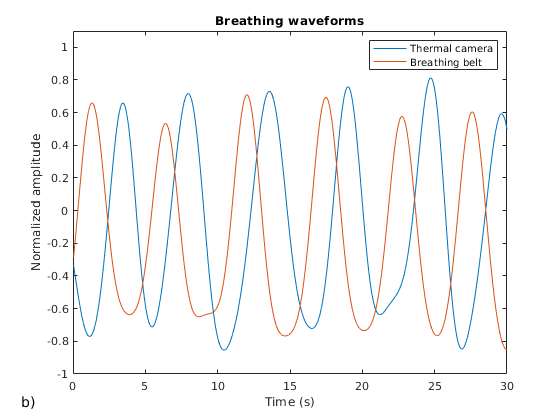

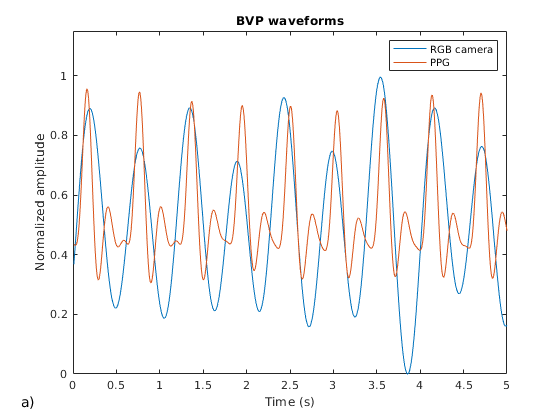

fs_br=25;
fs_hr=100;
BVP=csvread('HR_waveform.csv',1,0);
BR=csvread('RR_waveform.csv',1,0);

t=1/fs_br:1/fs_br:length(BR)/fs_br;
figure,
plot(t,BR(:,2),t,BR(:,3))  
title('Breathing waveforms')
xlabel('Time (s)')
ylabel('Normalized amplitude')
legend('Thermal camera','Breathing belt')
xlim([0,30])
ylim([-1 1.1])
annonation_save('b)',"Fig11.4b.jpg", 1);

t=1/fs_hr:1/fs_hr:length(BVP)/fs_hr;
figure,
plot(t,BVP(:,2),t,BVP(:,3))  
title('BVP waveforms')
xlabel('Time (s)')
ylabel('Normalized amplitude')
legend('RGB camera','PPG')
xlim([0,5])
ylim([0 1.15])
annonation_save('a)',"Fig11.4a.jpg", 1);